% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Tamaño de representación
Nx = 2048;
Ny = 2048;

% Condiciones de Muestreo
dx =6.513*mm;
dy =6.513*mm;

lambda = 633*nm;
k=(2*pi)/lambda;

distPropagacion=73*mm

distPropagacion = 0.0730

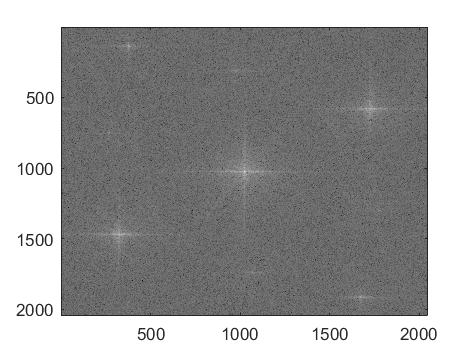


%Leer la imagen del holograma
ImHolo=imread("Hologram.tiff"); %Pixeles de 2048*2048
colormap("gray");



%Sacar transformada de Fourier del holograma
FourierTransform=fft2(ImHolo);
FFTHOLO = (fftshift(fft2(ImHolo)));
Transformada=imagesc(log(abs(fftshift(FourierTransform))));


% Se sacan los máximos
[maximosY,maximosX] = find(abs(FFTHOLO) == max(abs(FFTHOLO),[],"all"))

maximosY = 1025

maximosX = 1025

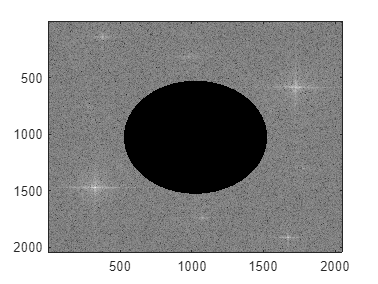


%Como el máximo central es el de mayor intensidad se elimina con un filtro
%para buscar los otros dos máximos

FFTHoloSinCentro = FFTHOLO.*(~filtroCircular([1025 1025],500,size(FFTHOLO)));
imagesc(log10(abs(FFTHoloSinCentro)))


%Deben encontrarse los dos máximos que dan cuenta de la información del
%objeto y onda de referencia

[maximosY1,maximosX1] = find(abs(FFTHoloSinCentro) == max(abs(FFTHoloSinCentro),[],"all"))

maximosY1 =         1469
         581


maximosX1 =          324
        1726


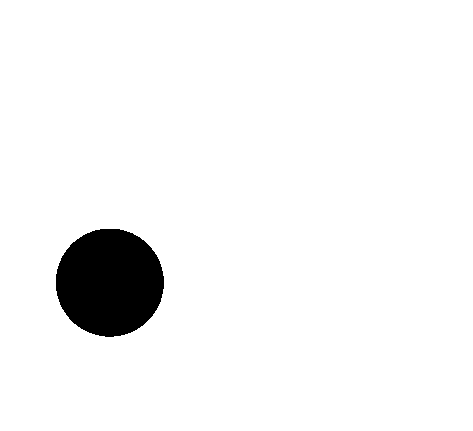


%Creación de la máscara para la selección de un orden

Mascara= (~filtroCircular([324 1469],300,size(FFTHOLO)));
imshow(Mascara);

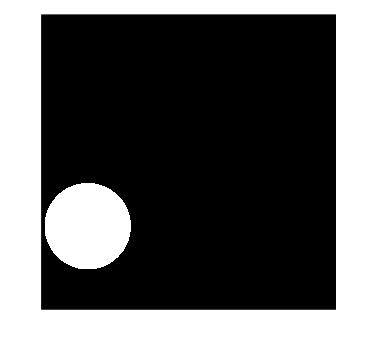

Filtro = imcomplement(Mascara); 
imshow(Filtro)

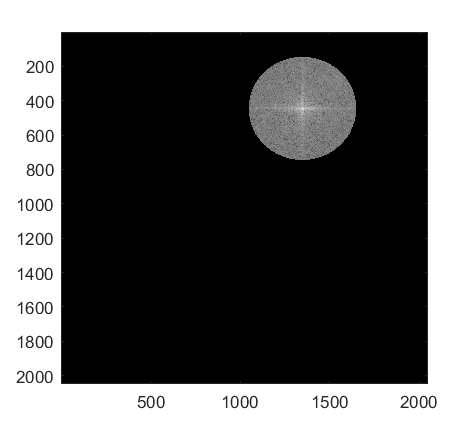

ImagenPropagar =   Image with properties:

           CData: [2048×2048 double]
    CDataMapping: 'scaled'

  Show all properties



%Se multiplica la transformada por la máscara para obtener un solo orden
OrdenMas=FFTHOLO.*Filtro;
ImagenPropagar=imagesc(log(abs(fftshift(OrdenMas.^2))))


angleX=atan(0);
angleY=((pi/2)-angleX);

Onda1= plane_wave2D(Nx, Ny, angleX, angleY, dx, dy, k)

Onda1 =    0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i   0.9983 + 0.0575i
  -0.9454 + 0.3260i  -0.9454 + 0.3260i  -

campoEntrada=OrdenMas.*Onda1

campoEntrada = 	1.0e+07 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   

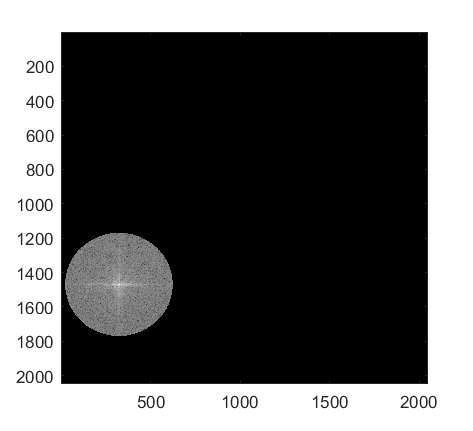

imagesc(log10(abs(campoEntrada)))


c=transformadaFresnel(campoEntrada,dx,dy,distPropagacion, lambda)

c = 	1.0e+-3 *

  -0.0762 - 0.1031i  -0.1030 - 0.0039i  -0.0502 + 0.0620i   0.0200 + 0.0646i   0.0683 + 0.0160i   0.0563 - 0.0615i  -0.0309 - 0.0933i  -0.1044 - 0.0186i  -0.0616 + 0.0831i   0.0462 + 0.0818i   0.0834 - 0.0097i   0.0255 - 0.0718i  -0.0410 - 0.0557i  -0.0613 - 0.0082i  -0.0494 + 0.0285i  -0.0235 + 0.0508i   0.0134 + 0.0543i   0.0446 + 0.0281i   0.0433 - 0.0131i   0.0119 - 0.0336i  -0.0170 - 0.0222i  -0.0255 + 0.0012i  -0.0172 + 0.0234i   0.0099 + 0.0357i   0.0440 + 0.0143i   0.0393 - 0.0368i  -0.0180 - 0.0570i  -0.0644 - 0.0087i  -0.0406 + 0.0562i   0.0259 + 0.0657i   0.0650 + 0.0188i   0.0520 - 0.0318i   0.0145 - 0.0506i  -0.0175 - 0.0422i  -0.0365 - 0.0206i  -0.0383 + 0.0102i  -0.0116 + 0.0339i   0.0266 + 0.0178i   0.0226 - 0.0326i  -0.0413 - 0.0495i  -0.0964 + 0.0185i  -0.0541 + 0.1224i   0.0811 + 0.1443i   0.1859 + 0.0251i   0.1347 - 0.1415i  -0.0413 - 0.1829i  -0.1599 - 0.0507i  -0.0997 + 0.1054i   0.0545 + 0.1179i   0.1265 - 0.0079i
   0.1232 - 0.0787i   0.0102 - 0.

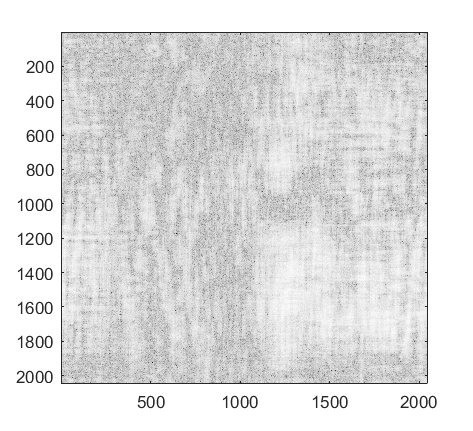

imagesc(log(abs(fftshift(c.^2))))